# 8. Input

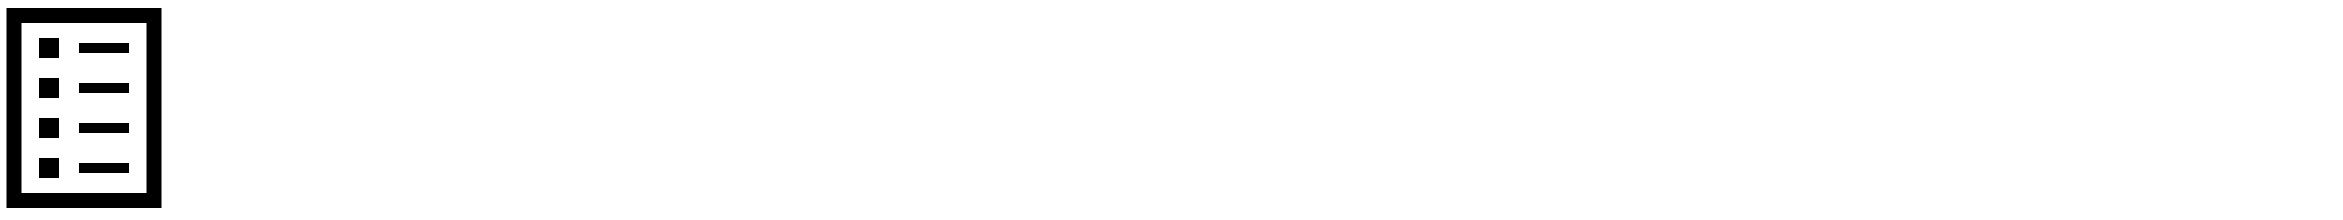

Input requests information from the person using the computer and pauses the program until a value is entered. Input can also be data from a file. This module shows how to access input data from either a user or a file.

For the final project egg incubator controller, certain types of eggs may require a different input and you could put that in your code to change the desired temperature. You could also use `input` to manually change power to the heaters.

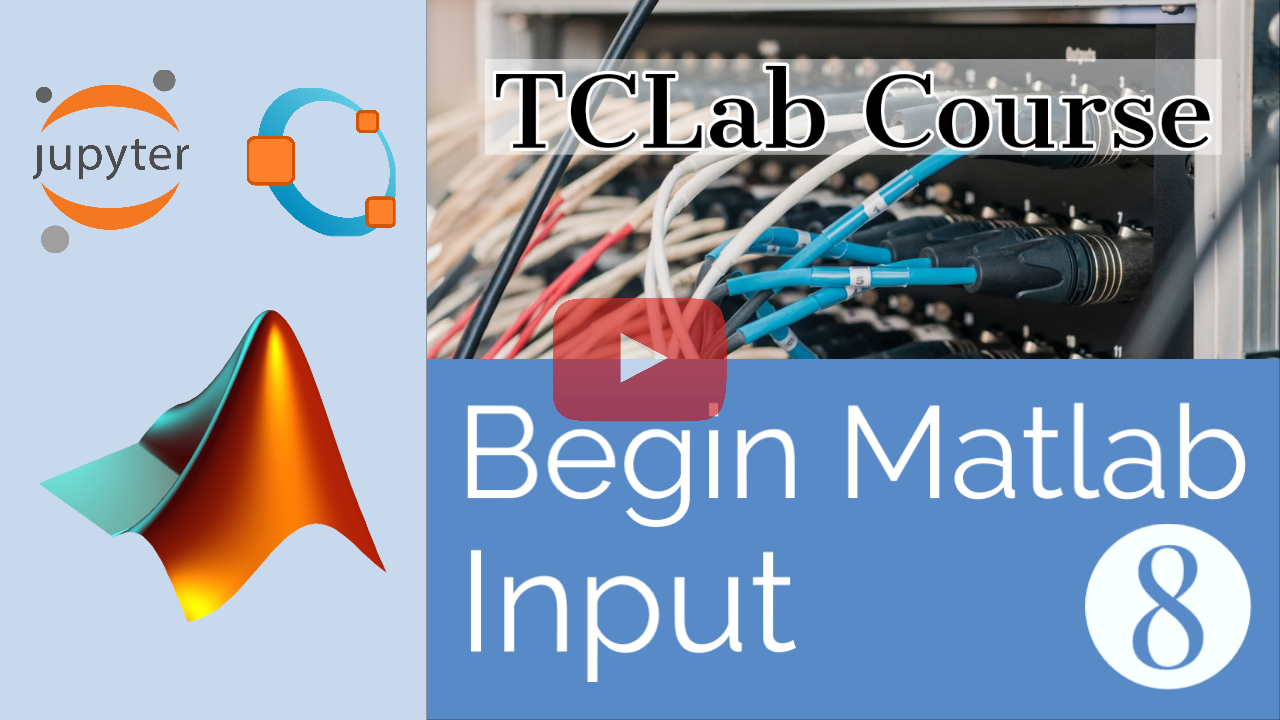

[Click here to watch the video: Matlab 👩‍💻 File and User Input](https://www.youtube.com/watch?v=ylosOcH4yYY&list=PLLBUgWXdTBDhJJnJW2q2G7e84MZM6dxRN)

If you run the code below, it asks you for a number. If they enter a number with a decimal or as a string, you need to turn `eggs` **double** into an **integer** with the function `round()` or `int64()`. Use these functions to change types.

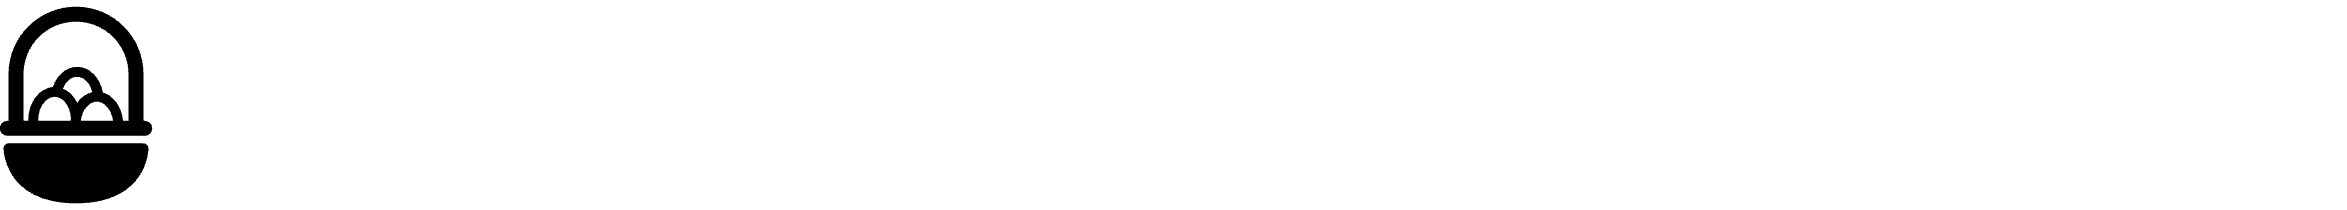

eggs = input("How many eggs do you have? ")
% make eggs into an integer
% change eggs-2 back into a string
disp(["Your hatchlings are ", eggs-2, ' because two are still developing'])

You can also make the input change into an **integer** on the same line as the input.

number = round(input('Enter a number: '))
disp(number + 5)

### **Save Data File**

You can save data to a file with `save -ascii filename data` as shown below to save the input `number` to a file `number.txt`. The `-ascii` flag tells the computer to save the file in a human-readable form as a text file instead of a binary file. A binary file takes up less storage space and is faster to write and read by the computer but it is harder to inspect the file contents by another program.

myNumber = 8;
save -ascii -append number.txt myNumber

Use the flag `-append` to add to the end of the file instead of replacing the contents.

### **Load Data File**

Data files on your computer such as a Comma Separated Value (CSV) file or a regular text file can also be an input to your program. There is more information on [importing and analyzing data files](https://apmonitor.com/che263/index.php/Main/MatlabDataAnalysis). To load a file, use the `load` command followed by the file name.

load number.txt

This loads the contents of number.txt back into Matlab as a variable name that does not include the file extension (`.txt`). In this case, the variable `number` is updated.

### **Activity**

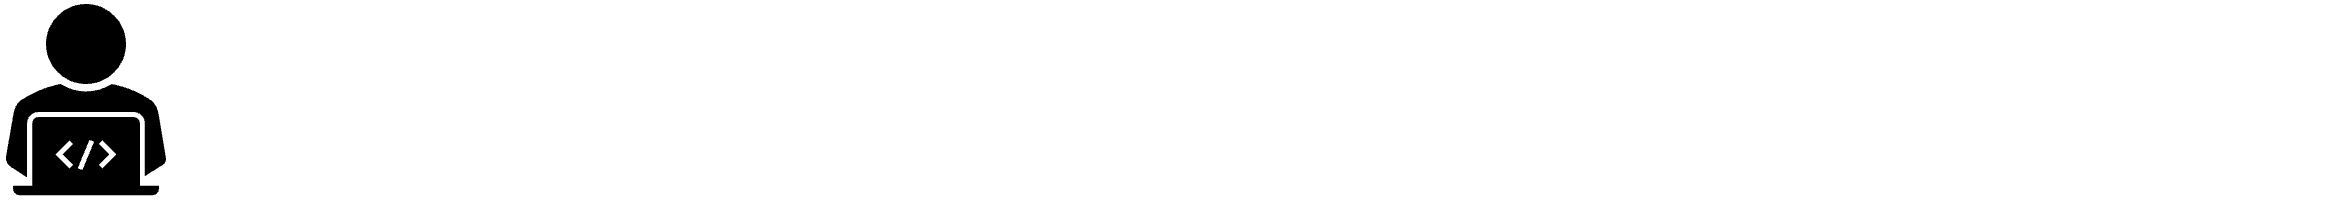

Make a function that uses `input` for two values. The function should take two values, add the second number to the first number 20 times, then return the new value. Make sure to use a `for` loop in your function. Go back to the lesson on **Loops** or **Functions** if you get stuck.

% Define a function

% Use a for loop

disp('') % Call the function

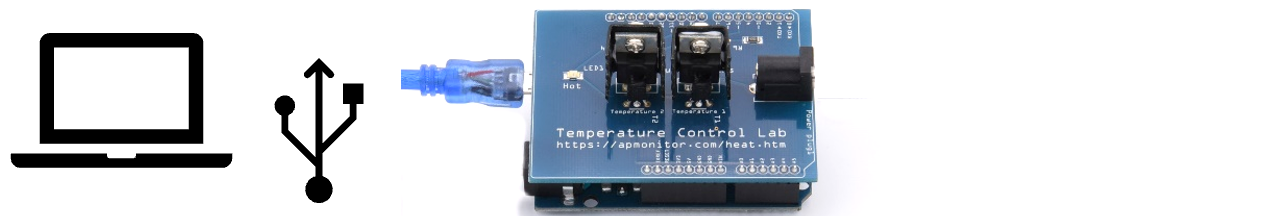

Use a `while` loop to keep asking the user for input for the **LED** light power percentage. Make the code so if the entered value is 0, the program stops. Save the sequence of values to a text file.

This could be something used in the final project when you design an incubator. You can set the target temperature to different values or turn off the system completely.